# **Task_01:**      Update the spring Stiffnesses 

In this task we'll vary the spring stiffness of the system until we get resonant frequencies that match a TARGET (e.g.: measured) set of frequences

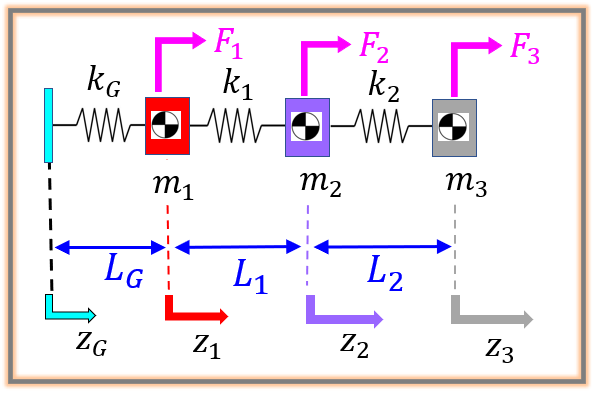

## Newton derivation of the Mechanical Equations of motion

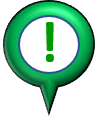The Newton 2nd Law derivation is summarized in the function file:

- [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

## Clear your workspace

clear

## Define floor masses

[m1, m2, m3] = deal( 0.508  );

## Define Target natural frequencies in $\left(\mathrm{Hz}\right)$

TGT_f_Hz_col = [0.95; 3; 4.6];

## Do a parameter sweep over the spring stiffness

- Assume all springs have the same stiffness

k_list    = [50:0.1:200];
f_Hz_list = zeros(3, numel(k_list));
err_list  = zeros(1, numel(k_list));

for kk = 1:numel(k_list)

    [kg, k1, k2] = deal(  k_list(kk)  );

    [smd_M, smd_C, smd_K, mck_OBJ] = ...
        bh_newton_smd_3dof_model_MCK( m1, m2, m3, ...
                                      kg, k1, k2, ...
                                  "DAMPING_RAYLEIGH",  [0, 1e-3] );

    [V_mat, ~, w_table] = bh_do_modal_analysis( smd_M, smd_K, "tf_do_plots",false );
    f_Hz_list(:,kk)     = w_table.f_Hz;
    err_list(kk)        =  norm( f_Hz_list(:,kk) - TGT_f_Hz_col  );
end

Plot stuff

figure
hax(1) = subplot(2,1,1);
    plot(k_list, f_Hz_list(1,:), 'r', ...
         k_list, f_Hz_list(2,:), 'g', ...
         k_list, f_Hz_list(3,:), 'b', "LineWidth",2);
            xlabel('Stiffness (k)');
            ylabel('Natural Frequencies (Hz)');
            title('Natural Frequencies vs Stiffness');
            %legend('Mode 1', 'Mode 2', 'Mode 3');
            grid on;
            hold on
            yline(TGT_f_Hz_col, "--m")

hax(2) = subplot(2,1,2);
    plot(k_list, err_list, "m.", "LineWidth",2);
        xlabel('Stiffness (k)');
        ylabel('NORM diff');
        title('NORM diff vs Stiffness');
        grid on;

Where was MINIMUM error:

[~,IND] = min(err_list);

## And what spring stiffness produces this

k_best  = k_list(IND)

xline(k_best,"m", LineWidth=2,Parent=hax(1))

## Do Final Modal Analysis on this SMD system

 [kg, k1, k2] = deal(  k_best  );

[smd_M, smd_C, smd_K, mck_OBJ] = ...
        bh_newton_smd_3dof_model_MCK( m1, m2, m3, ...
                                      kg, k1, k2, ...
                                      "DAMPING_RAYLEIGH",  [0, 1e-3] );

[~, ~, w_table] = bh_do_modal_analysis( smd_M, smd_K, "tf_do_plots",false );

w_table

So How close are we now to the TARGET set of frequencies ?

w_table.f_Hz ./ TGT_f_Hz_col
%sqrt(w_table.f_Hz ./ TGT_f_Hz_col)